clear all
clc
close all

z33 = zeros(3,3);
% x = [Np, Ep, psip, u, v, r, tauN, tauE, tauPSI]
% Ship characteristics
[M, D, Athr] = loadvars();
A = [z33,    eye(3),    z33;
     z33, -inv(M)*D, inv(M);
     z33,       z33,   Athr];
B = [z33, z33, -Athr]';
C = eye(3,9);
D = 0;

% Stability
evec = eig(A);
n_crtb = rank(ctrb(A, B));
n_obse = rank(obsv(A, C));

tau_sys_ol = 1./abs(evec);
Ts = ceil(min(tau_sys_ol))/10;

[F,G] = c2d(A,B,Ts);

n_crtb = rank(ctrb(F, G));
n_obse = rank(obsv(F, C));

eig(F);

## Discrete fsf

des_lambda = [-1, -1.2, -1.4, -1.6, -1.8, -2, -2.2, -2.4, -2.6]

des_lambda =    -1.0000   -1.2000   -1.4000   -1.6000   -1.8000   -2.0000   -2.2000   -2.4000   -2.6000


disc_des_lambda = exp(des_lambda * Ts)

disc_des_lambda = 1.0e-06 *

    0.4564    0.0246    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


K = place(F, G, disc_des_lambda)

Error using place
The "place" command
could not place the
poles at the specified
locations. Probable
causes include:
* (A,B) is nearly
uncontrollable
* The specified
locations are too close
to each other.

## LQR

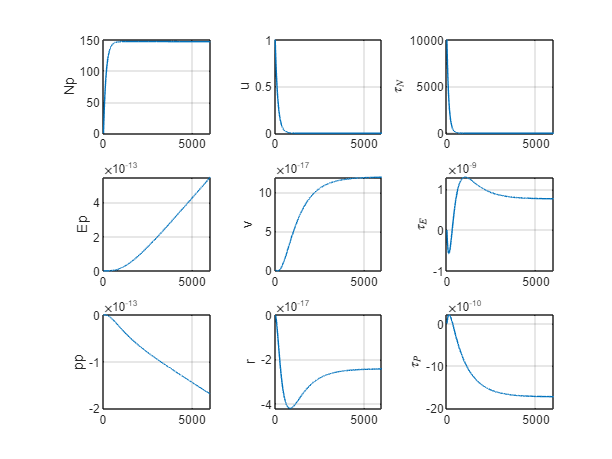

Q = diag([100, 10, 10, 0.1, 0.1, 0.1, 1000, 1000, 1000]);
R = diag([1000, 1000, 1000]);
[K,P,E] = lqr(A, B, Q, R);
Ak = A-B*K;
eig(Ak);

% Sim vars
SIMTIME = 6000;
SIMSTEP = 1;
N = SIMTIME/SIMSTEP;
n_contr = 9;
bias = [0, 0, 0, 1, 0.5, 1.2, 0, 0, 0]';
tau_wind = [0;0;0];
ref = [0;0;0]; 
x = zeros(n_contr, N+1);
x(:,1) = [0, 0, 0, 1, 0, 0, 10000, 0, 0];

% Ship loop
for i = 2:N+1
    
    u = - K * x(:,i-1) - tau_wind + ref;
    xdot = A * x(:,i-1) + B * u;
    x(:, i) = x(:, i-1) + SIMSTEP * xdot;
end

figure
subplot(331), plot(x(1, :)), grid, ylabel("Np")
subplot(334), plot(x(2, :)), grid, ylabel("Ep")
subplot(337), plot(x(3, :)), grid, ylabel("pp")

subplot(332), plot(x(4, :)), grid, ylabel("u")
subplot(335), plot(x(5, :)), grid, ylabel("v")
subplot(338), plot(x(6, :)), grid, ylabel("r")

subplot(333), plot(x(7, :)), grid, ylabel("$\tau_N$","Interpreter","latex")
subplot(336), plot(x(8, :)), grid, ylabel("$\tau_E$","Interpreter","latex")
subplot(339), plot(x(9, :)), grid, ylabel("$\tau_P$","Interpreter","latex")